t=linspace(0,10000,50)

t = 	1.0e+04 *

         0    0.0204    0.0408    0.0612    0.0816    0.1020    0.1224    0.1429    0.1633    0.1837    0.2041    0.2245    0.2449    0.2653    0.2857    0.3061    0.3265    0.3469    0.3673    0.3878    0.4082    0.4286    0.4490    0.4694    0.4898    0.5102    0.5306    0.5510    0.5714    0.5918    0.6122    0.6327    0.6531    0.6735    0.6939    0.7143    0.7347    0.7551    0.7755    0.7959    0.8163    0.8367    0.8571    0.8776    0.8980    0.9184    0.9388    0.9592    0.9796    1.0000


funx = @(t) 16*sin(t).*sin(t).*sin(t)

funx = function_handle with value:
    @(t)16*sin(t).*sin(t).*sin(t)


funy = @(t) 13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t)

funy = function_handle with value:
    @(t)13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t)



% fplot(funx,funy,"LineWidth",5,"Color",'r')
%a=0.4;
%b=1;

funconh=@(y,x) (x-a).^2*(x.^2+y.^2)-(b.^2)*(x.^2)

funconh = function_handle with value:
    @(y,x)(x-a).^2*(x.^2+y.^2)-(b.^2)*(x.^2)


subplot(2,2,4)

c = fimplicit(funconh, [-4 4 -1 2]);

hold on
%plot(funcon(),'.','color','r','Markersize', 20)
hold off
%c.LineWidth = 3;
%axis normal
phi = linspace(0,2*pi,100)

phi =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


subplot(2,2,1)
polarplot(phi,(sin(phi)).*(phi.^-1))
hold on
polarplot(0,0,'.','color','r','Markersize', 20)
hold off
subplot(2,2,2)
funconh=@(x,y) x.^2+y.^2-((sin(phi)).*(phi.^-1)).^2

funconh = function_handle with value:
    @(x,y)x.^2+y.^2-((sin(phi)).*(phi.^-1)).^2


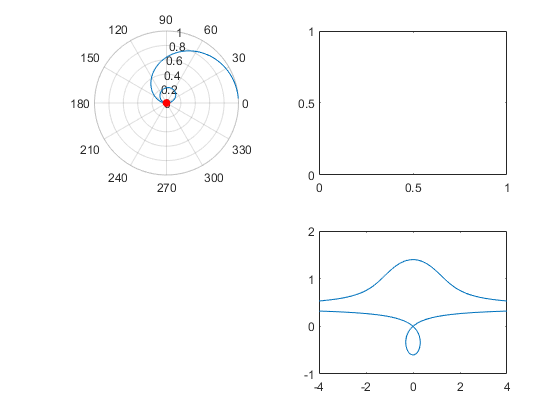

fimplicit(funconh, [-10 10 -10 10]);